% So lets start the dirty little code

## Global Variables

n = 100 % n is the number of elements per ring

n = 100

r = 100 % r is the number of rings

r = 100

N = n*r % which is the total number of nodes in the Network

N = 10000

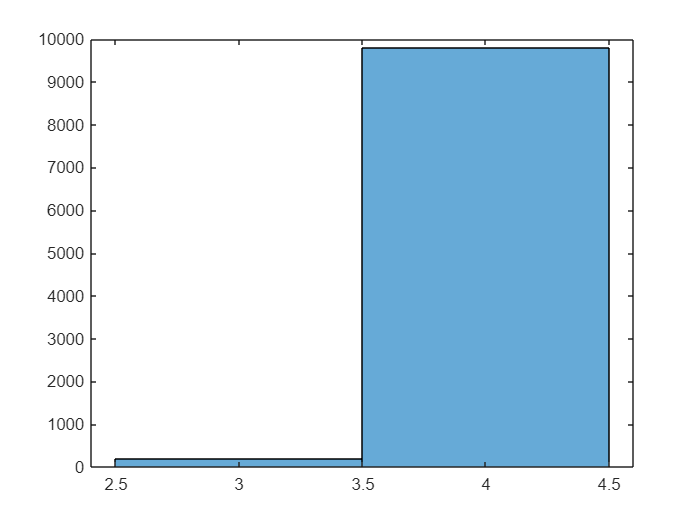


% Mechanical network
adj_mech = mech_network(n,r,1); % k is the number of neighbours / element on one side 

% Defining a Graph, to see how the plot would look like
mech_graph = graph(adj_mech)

mech_graph =   graph with properties:

    Edges: [19900×2 table]
    Nodes: [10000×0 table]


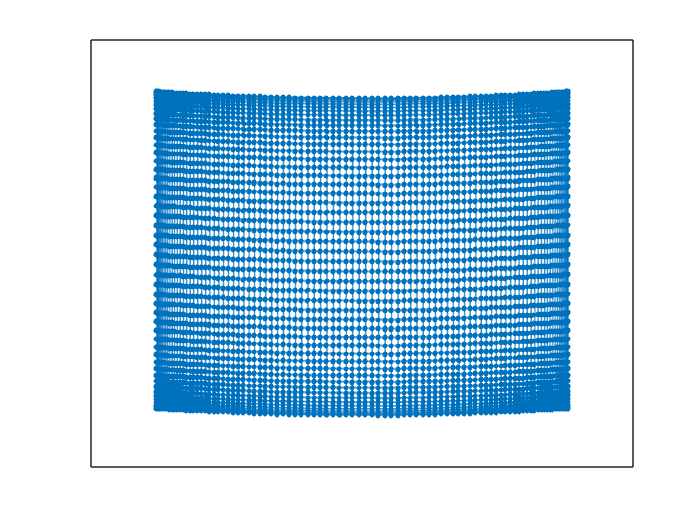

plot(mech_graph)


% Electrical Network
lap_elec = modify_to_elec(adj_mech,n,r,1); % the function that modifies the regular lattice to make the necessary modifications 

exc_value = 3*max(diag(-lap_elec));
% Now defining for the Refractory Phases

rng('default');
r_data = randi(25,[1,N]) % Randomly generated numbers

r_data =     21    23     4    23    16     3     7    14    24    25     4    25    24    13    21     4    11    23    20    24    17     1    22    24    17    19    19    10    17     5    18     1     7     2     3    21    18     8    24     1    11    10    20    20     5    13    12    17    18    19


r_data(1) = 5;
%r_standard = 3;
%r_data = r_standard*ones([N,1]); % Uniformaly generated Refractory Period

% Computational aspects 
no_iterations = 200;
SAN_freq = r_data(1)

SAN_freq = 5

% Memory of the states 
mem_s = zeros([N,no_iterations]); 
% Memory of the refractory state 
ref_mem = zeros([N,no_iterations]);

## State Variables

ps = ones([N,1]);
rs = zeros([N,1]);
ns = ones([N,1]);
rns = zeros([N,1]);

Initialisation

ps(1) = exc_value;
% Need to iterate over every time, Generate a new Vector and feed it back.
for i=1:no_iterations
    mem_s(:,i) = ps;
    ref_mem(:,i) = rs;
    next_state = next_v1(ps,rs,r_data,lap_elec,exc_value);
    ns = next_state(:,1);
    rns = next_state(:,2);
    ps(:) = ns(:);
    rs(:) = rns(:);
    if mod(i,SAN_freq)==0
        if ps(1) == 1
            ps(1) = exc_value;
        end
    end 
end

Thus if I write next_v1 we should be done and then visualisation

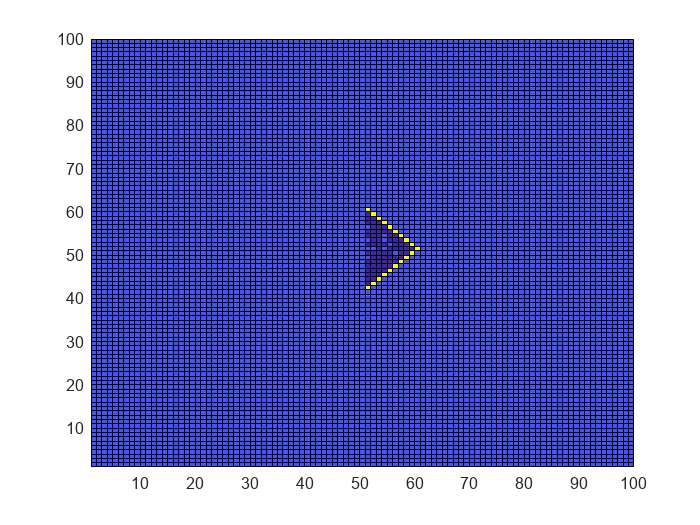

% Thus visualising the matrix as a coloured form
ns_long = mem_s(:,i);
ns_visualise_1 = reshape(ns_long,[n,r]);
ns_visualise = [ns_visualise_1((n/2)+1:n,(r/2)+1:r),ns_visualise_1(n/2+1:n,1:(r/2));ns_visualise_1(1:n/2,r/2+1:r),ns_visualise_1(1:n/2,1:r/2)];
h = pcolor(ns_visualise);
drawnow();
pause(0.3);
for i = 2:no_iterations
    ns_long = mem_s(:,i);
    ns_visualise_1 = reshape(ns_long,[n,r]);
    ns_visualise = [ns_visualise_1((n/2)+1:n,(r/2)+1:r),ns_visualise_1(n/2+1:n,1:(r/2));ns_visualise_1(1:n/2,r/2+1:r),ns_visualise_1(1:n/2,1:r/2)];
    set(h,'CData',ns_visualise);
    drawnow();
    pause(0.3);
end 

### Functions in the Network

Building the laplacian of the mechanical network

function y = mech_network(n,r,k)
    % for now building a regular lattice in a ring, and then just
    % connecting it vertically using identity elements
    matrix_size = n*r;
    ring = regular_lattice(n,k);
    vert = eye(n);
    % Building that matrix 
    adj = zeros([matrix_size,matrix_size]);
    adj(1:n,1:2*n) = [ring vert];
    adj(r*(n-1)+1:r*n,r*(n-2)+1:r*n) = [vert ring];
    for i = 1:(r-2)
        adj(i*n+1:(i+1)*n,(i-1)*n+1:(i+2)*n) = [vert, ring, vert];
    end
    %adj
    degrees = adj*ones([matrix_size,1]);
    histogram(degrees);
    %lap = np.zeros([matrix_size,matrix_size]);
    %lap = diag(degrees)+adj;
    y = adj;
end

Regular lattice

function y = regular_lattice(n,k)
    adj = zeros([n,n]);
    % Method 1
    % Adding the relevant diagonals
    for i = -k:k
        if i ~= 0
            adj = adj +diag(ones([n-abs(i),1]),i);
        end
    end 
    corner_matrix = triu(ones([k,k]));
    summation_matrix = [[zeros([k,n-k]) corner_matrix];[zeros([n-2*k,n])];[corner_matrix' zeros([k,n-k])]];
    adj = adj + summation_matrix;
    y = adj;
end

Electrical Network 

function y = modify_to_elec(mechanical_network, n, r, k)
    N = n*r;
    % How to make a vector that accesses all the states I need.. There is a
    % symmetry and that is the fact that, 

    %y = mechanical network ; % Status quo

    % for a basic one master node (1) connecting to a lot of nodes 
    adj_elec = mechanical_network;
    % Generating the boolean
    bool_taps = zeros([n*r,1]);
    for i = 1:2:(n-1)
        bool_taps(i*r+1) = 1;
    end
    %histogram(bool_taps);
    %adj_elec((bool_taps==1),1) = 1; % Remove these 2 for fun 
    %adj_elec(1,(bool_taps==1))=1; % Remove these 2 for fun 
    degrees_elec = adj_elec*ones([N,1]);
    histogram(degrees_elec);
    laplacian_elec = -diag(degrees_elec)+adj_elec;
    y = laplacian_elec;
end

Function that translates present state to next state

% State is a N size vector with the following encoding
function y = next_v1(present_state, refractory_state, refractory_info,laplacian_elec,excited_value)
    % When in Ground state 
    % Generating a bool 
    N = size(present_state,1);
    next_state = present_state;
    next_ref = refractory_state;
    GS_bool = (present_state==1); % All the elements that are in Ground state
    ES_bool = (laplacian_elec*present_state>0); % In gen the Elements for which it turns out to be>0 -> Mostly for both refractory phase and also .... Lite
    next_state(ES_bool&GS_bool) = excited_value; % The other values of GS_bool stay in Ground state
    % For the others we keep them at GS
    % refractory_state 
    % Those that are out of refractor should go up to GS
    Ref_bool = (present_state==-1); % All the elements that are in Refractory State
    reduced_ref = refractory_state - ones([N,1]); % The vector of reducing the refractory states by one number
    Out_of_ref = (reduced_ref==0);% those in the refractory state that are out of refractory state
    New_bool_1 = Ref_bool&Out_of_ref; % Among the refractory phases, only the ones that are out of the cycle of refraction
    next_state(New_bool_1) = 1; % Now in Ground state 
    next_ref(New_bool_1) = 0; % Now not in refractory phase anymore
    % Those that need to reduce by one
    In_ref = (reduced_ref>0); 
    New_bool_2 = (Ref_bool&In_ref); % Now among the refractory elements those that are still in refractory phase
    next_ref(In_ref) = reduced_ref(New_bool_2); % Updating the next_ref, but not the next_state because it will still be in refractory phase
    % Now Transition of Excited state 
    ES_old_bool = (present_state==excited_value); % All the elements that were in Excited State
    next_state(ES_old_bool) = -1; % Changing the element to 
    next_ref(ES_old_bool) = refractory_info(ES_old_bool); % making some zero elements non-zero
    y = [next_state,next_ref];
end